**Defining A and b**

v1 = [2, 3, 4, 5, 6];
v2 = [5, 7, 8, 11, 12];
x_data = v1';
b = v2';
A_matrix = ones(1, 5)';
A_matrix = [A_matrix x_data];

**Calling the Function LSsolver for Fit Coefficients**

[c1, c2] = LSsolver(A_matrix, b);
model_linear = c1 + c2*x_data;

**Plotting the Points and Linear Fit**

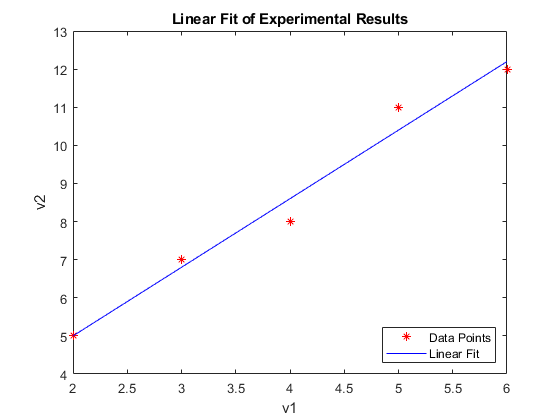

plot(v1,v2,"*r")
hold on
plot(x_data,model_linear,"b")
ylabel("v2")
xlabel("v1")
title("Linear Fit of Experimental Results")
legend("Data Points", "Linear Fit", "location", "southeast")

**Finding Approximation of v2**

v2 = interp1(x_data, model_linear, 4.6)

v2 =    9.679999999999994


From the Linear Fit it can be approximated that v2 is equal to 9.68